dataPath = 'DATASET/';
%
% 
dataUsage = 'Linear Acceleration Sensor';
fData = dir(fullfile(dataPath,strcat('*',dataUsage,'*.txt')));
RawData = cell(length(fData),12);
for i=1:length(fData)
    curAccelerationData = load(strcat(dataPath,fData(i).name));
    curRotationData = load(strcat(dataPath,strrep(fData(i).name,dataUsage,'Rotation Matrix')));
    
    
    idxID = strfind(fData(i).name,'ID');
    curID = str2double(fData(i).name(idxID+2:idxID+3));
    curGender = fData(i).name(idxID+5);
    idxSessionID = strfind(fData(i).name,'_');
    curSessionID = str2double([fData(i).name(idxID+2:idxID+3) fData(i).name(idxSessionID(2)+1:idxSessionID(3)-1)]);curOrder = str2double(fData(i).name(idxSessionID(end)+1:strfind(fData(i).name,'.txt')-1));
    
    curOrder = str2double(fData(i).name(idxSessionID(end)+1:strfind(fData(i).name,'.txt')-1));
 
    % [RawAccelerationData  RawRotationMatrixData ID Sex Session Order]
    RawData{i,1} = curAccelerationData;
    RawData{i,2} = curRotationData;
    RawData{i,3} = curID;
    RawData{i,4} = curGender;
    RawData{i,5} = curSessionID;
    RawData{i,6} = curOrder;    
end
%
%     PREPROCESSING:
% 
%    ACCELEROMETER DATA CALIBRATION
%   Input: [Raw_Acceleration_Data Rotation_Matrix]
%   Output: [Calibrated_Data] 
for i = 1: length(RawData)
   RawData{i,2} =  calibrateAccelerometerData(RawData{i,1},RawData{i,2});
end
%
%    LINEAR INTERPOLATION
%   Input: [accelerometer data]
%   Ouput: [Interpolated_accelerometer_data]

for i =1: length(RawData)
   RawData{i,2} = linearInterpolation(RawData{i,2});  
end
%
%    NOISE ELIMINATION
%   Input:   [accelerometer_data]
%   Output:  [noise_reduced_accelerometer_data]
%
for i = 1: length(RawData)
   RawData{i,2} = eliminateNoise('db6',2,RawData{i,2}); 
end

%
%    SEGMENTATION
%
%    GAIT CYCLE DETECTION
%   Input:  [accelerometer_data ]
%   Output: [peak_position]
for i = 1: length(RawData)
    peak_pos = detectGaitCycle(RawData{i,2});
    
    RawData{i,7} = peak_pos;
end
%
%   GAIT CYCLE BASED SEGMENTATION

%  Input:  [accelerometer_data peak_position]
%  Output: [1-gait cycle based segments]

for i = 1:length(RawData)
   segments = segment2GaitCycle(RawData{i,2},RawData{i,7});
    
   RawData{i,8} = segments;

end
%
%   GAIT PATTERN EXTRACTION
%  Input: [1-gait cycle based segments n p]
%  Output:[gait_patterns]
n = 4; p = 0.5;
for i=1:length(RawData)
    gait_patterns = extractGaitPattern(RawData{i,8},n,p);
    RawData{i,9} = gait_patterns;
end

## FEATURE EXTRACTION

`Input:  [Gait Pattern]`

`Output: [feature vectors]`

for i =1:length(RawData)
   time_features = extractFeature_timedomain(RawData{i,9});
   frequency_features = extractFeature_frequencydomain(RawData{i,9});
   RawData{i,10} = time_features;
   RawData{i,11} = frequency_features;
end
%
%    FEATURE VECTOR CONCATENATION
%       
% 
selectedAxis = [3 4 5]; % use features of Z, MXY, MXYZ axes
for i =1:length(RawData)
    curTimeFeature = RawData{i,10};
    curFrequencyFeature = RawData{i,11};
    concatFeature = {};
    for ii = 1:length(curTimeFeature)
    lastTimeFeature = curTimeFeature{ii,1}(end);
    concatTimeFeature = [lastTimeFeature ];
    for iii = 1:length(selectedAxis)
        concatTimeFeature = [concatTimeFeature curTimeFeature{ii,1}(1:end-1,selectedAxis(iii))'];
    end
    %BASED ON FEATURE SELECTION
    %concatTimeFeature = [concatTimeFeature(2) concatTimeFeature(3) concatTimeFeature(1) concatTimeFeature(6:15) concatTimeFeature(4) concatTimeFeature(4+16) concatTimeFeature(4+32) concatTimeFeature(17+32)];
    %
    concatFrequencyFeature = [];
    for iii = 1:length(selectedAxis)
        concatFrequencyFeature = [concatFrequencyFeature curFrequencyFeature{ii,1}(:,selectedAxis(iii))'];
    end
    %BASED ON FEATURE SELECTION
    %concatFrequencyFeature = [ concatFrequencyFeature(41:end)];
    %
    concatFeature{ii,1} = [ concatFrequencyFeature concatTimeFeature];    
    end
    RawData{i,12} = concatFeature;
end
%
%    DATA DIVISION
%   
%  
dataTrain = RawData(mod(cell2mat(RawData(:,6)),2)==1,:);
dataTest = RawData(mod(cell2mat(RawData(:,6)),2)==0,:);
%
%    FEATURE MATRIX AND LABEL VECTOR GENERATION
%
%
% TRAINING part
featureMatTrain = [];
labelVecTrain = [];
sessionVecTrain = [];
for i = 1: length(dataTrain)
    featureMatTrain = [featureMatTrain;cell2mat(dataTrain{i,12})];
    tempVec = zeros(length(dataTrain{i,12}),1);
    tempVec(:) = dataTrain{i,3};
    labelVecTrain = [labelVecTrain; tempVec];
    tempVec = zeros(length(dataTrain{i,9}),1);
    tempVec(:) = dataTrain{i,5};
    sessionVecTrain = [sessionVecTrain;tempVec];
end

%TESTING part
featureMatTest = [];
labelVecTest = [];
sessionVecTest = [];
for i = 1: length(dataTest)
    featureMatTest = [featureMatTest;cell2mat(dataTest{i,12})];
    tempVec = zeros(length(dataTest{i,12}),1);
    tempVec(:) = dataTest{i,3};
    labelVecTest = [labelVecTest; tempVec];
    tempVec = zeros(length(dataTest{i,9}),1);
    tempVec(:) = dataTest{i,5};
    sessionVecTest = [sessionVecTest;tempVec];
    
end

## AUTHENTICATION

`  TRAINING`

`  Apply PCA to training data`

[featureMatTrain,eigenVec,meanVec] = eigenGait(featureMatTrain);

%    Normalize the training data
max_val = max(featureMatTrain);
min_val = min(featureMatTrain);
max_valTrain = repmat(max_val,size(featureMatTrain,1),1);
min_valTrain = repmat(min_val,size(featureMatTrain,1),1);
featureMatTrain = ((featureMatTrain-min_valTrain)./(max_valTrain-min_valTrain) - 0.5 ) *2;
% 
%  TESTING
%
%  Apply PCA to testing data 
meanMat = repmat(meanVec,size(featureMatTest,1),1);
featureMatTest = (featureMatTest - meanMat)*eigenVec;
%  normalize feature matrix based on max min values 
max_valTest = repmat(max_val,size(featureMatTest,1),1);
min_valTest = repmat(min_val,size(featureMatTest,1),1);
featureMatTest = ((featureMatTest-min_valTest)./(max_valTest-min_valTest) - 0.5 ) *2;

## AUTHENITCATION USING SVM

uniLabel =unique(labelVecTrain); 
stack_x_1 = {};
stack_x_2 = {};
stack_y_1  = {};
stack_y_2  = {};
for i = 1 :length(uniLabel)
    labelVecBinTrain = labelVecTrain;
    labelVecBinTrain(labelVecBinTrain(:)~=(uniLabel(i)))=-1;
    labelVecBinTrain(labelVecBinTrain(:)==(uniLabel(i)))=1;
    unbalanced_weight = round((length(labelVecBinTrain)-sum(labelVecBinTrain(:)==1))/sum(labelVecBinTrain(:)==1));    
    model = svmtrain(labelVecBinTrain,featureMatTrain,['-t 0 -b 1 -w1 1 ' '-w-1 ' num2str(unbalanced_weight) ]);  
    labelVecBinTest = labelVecTest;
    labelVecBinTest(labelVecBinTest(:)~=uniLabel(i))=-1;
    labelVecBinTest(labelVecBinTest(:)==uniLabel(i))=1;
    [l,a,deci]=svmpredict(labelVecBinTest,featureMatTest,model);

*
optimization finished, #iter = 991
obj = -73.951156, rho = 5.357005
nSV = 82, nBSV = 47
Total nSV = 82
*.*
optimization finished, #iter = 1125
obj = -70.509612, rho = 5.406600
nSV = 80, nBSV = 46
Total nSV = 80
*.*.*
optimization finished, #iter = 1451
obj = -69.610994, rho = 4.463025
nSV = 80, nBSV = 46
Total nSV = 80
*.*
optimization finished, #iter = 1489
obj = -71.283488, rho = 5.783776
nSV = 80, nBSV = 44
Total nSV = 80
*.*
optimization finished, #iter = 1252
obj = -68.398729, rho = 5.356344
nSV = 76, nBSV = 45
Total nSV = 76
..*....*
optimization finished, #iter = 6336
obj = -89.334421, rho = 5.679019
nSV = 94, nBSV = 54
Total nSV = 94


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.3743% (5241/5274) (classification)


*
optimization finished, #iter = 944
obj = -38.121952, rho = 4.887259
nSV = 54, nBSV = 25
Total nSV = 54
*
optimization finished, #iter = 817
obj = -33.489959, rho = 5.016354
nSV = 56, nBSV = 24
Total nSV = 56
*
optimization finished, #iter = 469
obj = -33.998113, rho = 4.545038
nSV = 51, nBSV = 24
Total nSV = 51
*
optimization finished, #iter = 328
obj = -32.137596, rho = 5.434050
nSV = 49, nBSV = 24
Total nSV = 49
*
optimization finished, #iter = 678
obj = -38.383610, rho = 4.882258
nSV = 54, nBSV = 23
Total nSV = 54
*
optimization finished, #iter = 669
obj = -43.086986, rho = 5.135194
nSV = 60, nBSV = 29
Total nSV = 60


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.6397% (5255/5274) (classification)


*
optimization finished, #iter = 419
obj = -9.914612, rho = 2.868951
nSV = 35, nBSV = 7
Total nSV = 35
*
optimization finished, #iter = 381
obj = -8.621222, rho = 2.937532
nSV = 30, nBSV = 4
Total nSV = 30
*
optimization finished, #iter = 335
obj = -8.867201, rho = 2.714611
nSV = 32, nBSV = 6
Total nSV = 32
*
optimization finished, #iter = 423
obj = -8.904113, rho = 2.874368
nSV = 37, nBSV = 4
Total nSV = 37
*
optimization finished, #iter = 257
obj = -8.609457, rho = 2.870664
nSV = 29, nBSV = 4
Total nSV = 29
*
optimization finished, #iter = 335
obj = -9.921579, rho = 2.877805
nSV = 35, nBSV = 7
Total nSV = 35


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.9621% (5272/5274) (classification)


*
optimization finished, #iter = 320
obj = -26.181064, rho = 3.331566
nSV = 47, nBSV = 20
Total nSV = 47
*
optimization finished, #iter = 291
obj = -23.718505, rho = 3.977542
nSV = 45, nBSV = 17
Total nSV = 45
*
optimization finished, #iter = 641
obj = -21.768089, rho = 3.677524
nSV = 50, nBSV = 17
Total nSV = 50
*
optimization finished, #iter = 772
obj = -24.639524, rho = 3.252171
nSV = 50, nBSV = 17
Total nSV = 50
*
optimization finished, #iter = 456
obj = -27.596842, rho = 3.823491
nSV = 51, nBSV = 22
Total nSV = 51
*
optimization finished, #iter = 837
obj = -28.519034, rho = 3.941605
nSV = 52, nBSV = 21
Total nSV = 52


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.8862% (5268/5274) (classification)


*.*.*
optimization finished, #iter = 2633
obj = -68.350881, rho = 3.188527
nSV = 90, nBSV = 49
Total nSV = 90
.*..*
optimization finished, #iter = 3351
obj = -75.644605, rho = 2.879240
nSV = 88, nBSV = 48
Total nSV = 88
*.*
optimization finished, #iter = 1277
obj = -67.675021, rho = 2.507602
nSV = 86, nBSV = 49
Total nSV = 86
.*.*
optimization finished, #iter = 2355
obj = -68.020994, rho = 2.818654
nSV = 84, nBSV = 46
Total nSV = 84
*
optimization finished, #iter = 790
obj = -74.364870, rho = 3.130480
nSV = 87, nBSV = 52
Total nSV = 87
.*.*
optimization finished, #iter = 2473
obj = -83.170413, rho = 3.038762
nSV = 96, nBSV = 58
Total nSV = 96


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.2984% (5237/5274) (classification)


*..*....*
optimization finished, #iter = 6531
obj = -208.826774, rho = 4.332861
nSV = 157, nBSV = 116
Total nSV = 157
.*..*
optimization finished, #iter = 3397
obj = -190.164464, rho = 3.985227
nSV = 144, nBSV = 104
Total nSV = 144
.*.*
optimization finished, #iter = 2420
obj = -201.625111, rho = 4.531999
nSV = 146, nBSV = 111
Total nSV = 146
.*.*
optimization finished, #iter = 2172
obj = -197.403997, rho = 4.401748
nSV = 147, nBSV = 112
Total nSV = 147
.*..*
optimization finished, #iter = 3477
obj = -199.920560, rho = 4.208843
nSV = 149, nBSV = 112
Total nSV = 149
...*.*.*
optimization finished, #iter = 5008
obj = -248.808407, rho = 4.422458
nSV = 176, nBSV = 138
Total nSV = 176


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.8953% (5163/5274) (classification)


*
optimization finished, #iter = 832
obj = -120.598553, rho = 5.110810
nSV = 105, nBSV = 73
Total nSV = 105
*
optimization finished, #iter = 873
obj = -99.373298, rho = 4.282017
nSV = 89, nBSV = 59
Total nSV = 89
*.*
optimization finished, #iter = 1801
obj = -106.247679, rho = 4.730626
nSV = 102, nBSV = 66
Total nSV = 102
*.*
optimization finished, #iter = 1209
obj = -106.369620, rho = 4.665187
nSV = 99, nBSV = 65
Total nSV = 99
.*
optimization finished, #iter = 1929
obj = -112.584388, rho = 4.554741
nSV = 107, nBSV = 71
Total nSV = 107
*.*
optimization finished, #iter = 1333
obj = -135.675593, rho = 5.340901
nSV = 116, nBSV = 83
Total nSV = 116


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.8623% (5214/5274) (classification)


..*.......*.*
optimization finished, #iter = 10007
obj = -241.355652, rho = 1.161291
nSV = 164, nBSV = 121
Total nSV = 164
....*..*
optimization finished, #iter = 6105
obj = -214.810829, rho = 1.759961
nSV = 146, nBSV = 108
Total nSV = 146
..*..*
optimization finished, #iter = 4522
obj = -226.807636, rho = 1.307438
nSV = 158, nBSV = 114
Total nSV = 158
..*....*
optimization finished, #iter = 6013
obj = -229.205888, rho = 1.996895
nSV = 156, nBSV = 116
Total nSV = 156
....*..*.*
optimization finished, #iter = 7422
obj = -229.358457, rho = 1.315364
nSV = 157, nBSV = 115
Total nSV = 157
.....*................*.*
optimization finished, #iter = 21535
obj = -287.993515, rho = 1.051128
nSV = 190, nBSV = 144
Total nSV = 190


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.2886% (5131/5274) (classification)


...*..................*
optimization finished, #iter = 21280
obj = -216.562942, rho = 3.364181
nSV = 156, nBSV = 110
Total nSV = 156
..*.....*.....*
optimization finished, #iter = 11984
obj = -193.275521, rho = 1.808372
nSV = 143, nBSV = 97
Total nSV = 143
...*...*
optimization finished, #iter = 6488
obj = -204.786728, rho = 2.033246
nSV = 144, nBSV = 103
Total nSV = 144
..*.......*..*
optimization finished, #iter = 10892
obj = -206.907494, rho = 3.228553
nSV = 145, nBSV = 105
Total nSV = 145
..*.......*.....*
optimization finished, #iter = 14246
obj = -208.585566, rho = 2.281169
nSV = 148, nBSV = 105
Total nSV = 148
...*......*
optimization finished, #iter = 9144
obj = -258.937274, rho = 2.196199
nSV = 173, nBSV = 130
Total nSV = 173


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.4782% (5141/5274) (classification)


.*...*.*
optimization finished, #iter = 4328
obj = -206.486363, rho = 3.384712
nSV = 146, nBSV = 108
Total nSV = 146
....*..*
optimization finished, #iter = 6293
obj = -182.178460, rho = 3.345003
nSV = 134, nBSV = 94
Total nSV = 134
..*....*..*
optimization finished, #iter = 8371
obj = -192.245911, rho = 3.917662
nSV = 142, nBSV = 100
Total nSV = 142
.*..*
optimization finished, #iter = 3215
obj = -188.296349, rho = 4.836445
nSV = 141, nBSV = 101
Total nSV = 141
..*...*.*
optimization finished, #iter = 5867
obj = -196.263095, rho = 3.566396
nSV = 142, nBSV = 101
Total nSV = 142
...*...*
optimization finished, #iter = 6253
obj = -244.820766, rho = 3.575780
nSV = 165, nBSV = 126
Total nSV = 165


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.3075% (5132/5274) (classification)


.*
optimization finished, #iter = 1511
obj = -126.437919, rho = 6.964842
nSV = 114, nBSV = 82
Total nSV = 114
.*..*
optimization finished, #iter = 3046
obj = -119.724160, rho = 7.400987
nSV = 114, nBSV = 78
Total nSV = 114
.*..*
optimization finished, #iter = 3023
obj = -123.977076, rho = 7.086147
nSV = 116, nBSV = 79
Total nSV = 116
*..*
optimization finished, #iter = 2189
obj = -132.339572, rho = 6.612434
nSV = 119, nBSV = 82
Total nSV = 119
.*.*
optimization finished, #iter = 2663
obj = -133.219617, rho = 7.388336
nSV = 121, nBSV = 84
Total nSV = 121
..*..*
optimization finished, #iter = 4019
obj = -155.698523, rho = 7.673872
nSV = 134, nBSV = 95
Total nSV = 134


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.8244% (5212/5274) (classification)


.*.*
optimization finished, #iter = 2037
obj = -68.489006, rho = 6.397697
nSV = 84, nBSV = 51
Total nSV = 84
*.*
optimization finished, #iter = 1133
obj = -56.303716, rho = 6.394623
nSV = 75, nBSV = 41
Total nSV = 75
*.*
optimization finished, #iter = 1090
obj = -59.833382, rho = 5.889614
nSV = 81, nBSV = 46
Total nSV = 81
*.*
optimization finished, #iter = 1107
obj = -65.487156, rho = 6.174292
nSV = 83, nBSV = 49
Total nSV = 83
*.*
optimization finished, #iter = 1185
obj = -56.138071, rho = 6.413434
nSV = 76, nBSV = 41
Total nSV = 76
*.*.*
optimization finished, #iter = 2147
obj = -71.228354, rho = 6.619221
nSV = 92, nBSV = 55
Total nSV = 92


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.8104% (5264/5274) (classification)


.*.*
optimization finished, #iter = 2241
obj = -164.530840, rho = 7.265861
nSV = 141, nBSV = 102
Total nSV = 141
.*.*
optimization finished, #iter = 2462
obj = -144.590422, rho = 6.606256
nSV = 130, nBSV = 89
Total nSV = 130
.*..*
optimization finished, #iter = 3203
obj = -145.286722, rho = 7.513677
nSV = 130, nBSV = 93
Total nSV = 130
*.*.*
optimization finished, #iter = 2127
obj = -159.028326, rho = 6.799237
nSV = 132, nBSV = 94
Total nSV = 132
.*.*
optimization finished, #iter = 2727
obj = -159.523251, rho = 7.494679
nSV = 133, nBSV = 96
Total nSV = 133
.*.*
optimization finished, #iter = 2722
obj = -192.822088, rho = 8.097355
nSV = 157, nBSV = 119
Total nSV = 157


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.7296% (5207/5274) (classification)


....*.....*
optimization finished, #iter = 9105
obj = -253.026820, rho = 5.052102
nSV = 175, nBSV = 134
Total nSV = 175
..*.....*
optimization finished, #iter = 7840
obj = -216.766324, rho = 6.521633
nSV = 161, nBSV = 121
Total nSV = 161
...*.*
optimization finished, #iter = 4950
obj = -239.650120, rho = 6.043369
nSV = 168, nBSV = 130
Total nSV = 168
...*.....*
optimization finished, #iter = 8660
obj = -236.963614, rho = 5.153057
nSV = 169, nBSV = 127
Total nSV = 169
..*...*...*
optimization finished, #iter = 8281
obj = -242.566533, rho = 5.037017
nSV = 167, nBSV = 128
Total nSV = 167
..*..*
optimization finished, #iter = 4208
obj = -300.216726, rho = 5.914391
nSV = 198, nBSV = 160
Total nSV = 198


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.0231% (5117/5274) (classification)


*
optimization finished, #iter = 763
obj = -39.581208, rho = 4.726297
nSV = 53, nBSV = 26
Total nSV = 53
*.*
optimization finished, #iter = 1143
obj = -36.392148, rho = 4.577342
nSV = 59, nBSV = 23
Total nSV = 59
*.*
optimization finished, #iter = 1494
obj = -36.174196, rho = 5.081067
nSV = 56, nBSV = 23
Total nSV = 56
*
optimization finished, #iter = 774
obj = -33.402400, rho = 4.972881
nSV = 57, nBSV = 22
Total nSV = 57
*
optimization finished, #iter = 473
obj = -38.931183, rho = 4.850186
nSV = 52, nBSV = 26
Total nSV = 52
*
optimization finished, #iter = 755
obj = -44.126720, rho = 4.895112
nSV = 61, nBSV = 28
Total nSV = 61


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.7914% (5263/5274) (classification)


.*..*
optimization finished, #iter = 3726
obj = -197.316729, rho = 5.484517
nSV = 145, nBSV = 107
Total nSV = 145
.*..*
optimization finished, #iter = 3684
obj = -170.190638, rho = 5.070823
nSV = 130, nBSV = 91
Total nSV = 130
*
optimization finished, #iter = 976
obj = -175.568565, rho = 5.719406
nSV = 132, nBSV = 97
Total nSV = 132
.*
optimization finished, #iter = 1671
obj = -177.444880, rho = 5.878106
nSV = 136, nBSV = 99
Total nSV = 136
.*.*
optimization finished, #iter = 2726
obj = -175.127412, rho = 5.888170
nSV = 139, nBSV = 98
Total nSV = 139
.*..*
optimization finished, #iter = 3460
obj = -223.764807, rho = 6.448136
nSV = 160, nBSV = 123
Total nSV = 160


Model supports probability estimates, but disabled in predicton.
Accuracy = 97.3075% (5132/5274) (classification)


.*.*
optimization finished, #iter = 2251
obj = -145.408205, rho = 4.768024
nSV = 119, nBSV = 85
Total nSV = 119
.*...*
optimization finished, #iter = 4057
obj = -134.425737, rho = 4.304451
nSV = 115, nBSV = 77
Total nSV = 115
.*
optimization finished, #iter = 1872
obj = -112.852220, rho = 5.152261
nSV = 110, nBSV = 74
Total nSV = 110
.*.*
optimization finished, #iter = 2710
obj = -136.358041, rho = 5.073438
nSV = 119, nBSV = 81
Total nSV = 119
.*.*
optimization finished, #iter = 2855
obj = -131.471815, rho = 5.460475
nSV = 115, nBSV = 79
Total nSV = 115
.*.*
optimization finished, #iter = 2384
obj = -166.271515, rho = 5.295785
nSV = 134, nBSV = 96
Total nSV = 134


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.2366% (5181/5274) (classification)


*
optimization finished, #iter = 688
obj = -58.784079, rho = 5.221794
nSV = 73, nBSV = 42
Total nSV = 73
*.*
optimization finished, #iter = 1075
obj = -46.509439, rho = 5.156829
nSV = 70, nBSV = 33
Total nSV = 70
*
optimization finished, #iter = 772
obj = -57.046942, rho = 4.564797
nSV = 70, nBSV = 38
Total nSV = 70
*
optimization finished, #iter = 530
obj = -50.301007, rho = 4.662799
nSV = 68, nBSV = 37
Total nSV = 68
*.*
optimization finished, #iter = 1741
obj = -53.331119, rho = 5.064437
nSV = 75, nBSV = 40
Total nSV = 75
*
optimization finished, #iter = 514
obj = -62.361674, rho = 5.092908
nSV = 77, nBSV = 44
Total nSV = 77


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.7914% (5263/5274) (classification)


*.*
optimization finished, #iter = 1194
obj = -61.138958, rho = 3.722406
nSV = 79, nBSV = 44
Total nSV = 79
*.*
optimization finished, #iter = 1208
obj = -54.747043, rho = 3.820900
nSV = 70, nBSV = 37
Total nSV = 70
*.*
optimization finished, #iter = 1393
obj = -59.002613, rho = 3.653474
nSV = 79, nBSV = 42
Total nSV = 79
*.*
optimization finished, #iter = 1590
obj = -60.934442, rho = 3.658596
nSV = 79, nBSV = 44
Total nSV = 79
.*.*
optimization finished, #iter = 2491
obj = -60.643692, rho = 4.025161
nSV = 83, nBSV = 44
Total nSV = 83
*.*
optimization finished, #iter = 1007
obj = -69.272123, rho = 3.760223
nSV = 82, nBSV = 49
Total nSV = 82


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.1278% (5228/5274) (classification)


*.*
optimization finished, #iter = 1077
obj = -93.833868, rho = 7.602104
nSV = 98, nBSV = 61
Total nSV = 98
*
optimization finished, #iter = 711
obj = -79.867288, rho = 5.945731
nSV = 84, nBSV = 52
Total nSV = 84
.*.*
optimization finished, #iter = 2463
obj = -85.009732, rho = 6.441925
nSV = 92, nBSV = 56
Total nSV = 92
*.*
optimization finished, #iter = 1385
obj = -89.819928, rho = 7.010390
nSV = 94, nBSV = 59
Total nSV = 94
*.*
optimization finished, #iter = 1330
obj = -92.157079, rho = 6.482858
nSV = 95, nBSV = 62
Total nSV = 95
*.*
optimization finished, #iter = 1659
obj = -107.320876, rho = 7.122010
nSV = 111, nBSV = 71
Total nSV = 111


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.9192% (5217/5274) (classification)


*.*
optimization finished, #iter = 1055
obj = -39.383672, rho = 2.634904
nSV = 60, nBSV = 27
Total nSV = 60
*.*
optimization finished, #iter = 1474
obj = -32.620615, rho = 2.756454
nSV = 62, nBSV = 24
Total nSV = 62
*
optimization finished, #iter = 813
obj = -34.016579, rho = 2.849434
nSV = 58, nBSV = 24
Total nSV = 58
*
optimization finished, #iter = 543
obj = -34.935220, rho = 4.320748
nSV = 56, nBSV = 25
Total nSV = 56
*.*
optimization finished, #iter = 1021
obj = -35.087884, rho = 2.948931
nSV = 59, nBSV = 25
Total nSV = 59
*.*
optimization finished, #iter = 1159
obj = -42.097099, rho = 3.019493
nSV = 63, nBSV = 30
Total nSV = 63


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.7725% (5262/5274) (classification)


.*..*
optimization finished, #iter = 3755
obj = -116.323372, rho = 4.604922
nSV = 111, nBSV = 73
Total nSV = 111
.*
optimization finished, #iter = 1512
obj = -113.110549, rho = 4.588069
nSV = 103, nBSV = 68
Total nSV = 103
..*..*
optimization finished, #iter = 4557
obj = -108.139952, rho = 4.789862
nSV = 109, nBSV = 68
Total nSV = 109
.*..*.*
optimization finished, #iter = 4828
obj = -112.835694, rho = 5.109624
nSV = 109, nBSV = 70
Total nSV = 109
.*.*
optimization finished, #iter = 2024
obj = -108.809418, rho = 5.042754
nSV = 103, nBSV = 67
Total nSV = 103
.*.*
optimization finished, #iter = 2493
obj = -139.707517, rho = 5.797878
nSV = 124, nBSV = 83
Total nSV = 124


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.9003% (5216/5274) (classification)


..*
optimization finished, #iter = 2966
obj = -134.501995, rho = 2.684735
nSV = 120, nBSV = 84
Total nSV = 120
*.*
optimization finished, #iter = 1384
obj = -118.140740, rho = 3.355722
nSV = 104, nBSV = 71
Total nSV = 104
.*..*...*
optimization finished, #iter = 5572
obj = -124.513404, rho = 3.396198
nSV = 117, nBSV = 76
Total nSV = 117
.*.*
optimization finished, #iter = 2056
obj = -133.534205, rho = 3.450375
nSV = 119, nBSV = 82
Total nSV = 119
*.*
optimization finished, #iter = 1538
obj = -127.613077, rho = 3.616349
nSV = 115, nBSV = 80
Total nSV = 115
*.*
optimization finished, #iter = 1424
obj = -161.873425, rho = 3.522615
nSV = 135, nBSV = 98
Total nSV = 135


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.2556% (5182/5274) (classification)


*
optimization finished, #iter = 912
obj = -84.248775, rho = 6.033557
nSV = 93, nBSV = 59
Total nSV = 93
*.*
optimization finished, #iter = 1063
obj = -80.109765, rho = 6.054972
nSV = 90, nBSV = 57
Total nSV = 90
*.*
optimization finished, #iter = 1051
obj = -78.112317, rho = 6.129997
nSV = 88, nBSV = 55
Total nSV = 88
*..*
optimization finished, #iter = 2116
obj = -87.483561, rho = 5.911213
nSV = 97, nBSV = 59
Total nSV = 97
.*
optimization finished, #iter = 1458
obj = -80.701598, rho = 5.788740
nSV = 88, nBSV = 55
Total nSV = 88
.*.*
optimization finished, #iter = 2959
obj = -101.006954, rho = 6.423468
nSV = 105, nBSV = 68
Total nSV = 105


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.8623% (5214/5274) (classification)


*
optimization finished, #iter = 498
obj = -30.746151, rho = 4.497186
nSV = 54, nBSV = 24
Total nSV = 54
*
optimization finished, #iter = 833
obj = -30.082347, rho = 4.846771
nSV = 57, nBSV = 24
Total nSV = 57
*
optimization finished, #iter = 850
obj = -28.909389, rho = 4.696829
nSV = 55, nBSV = 24
Total nSV = 55
*
optimization finished, #iter = 464
obj = -33.399432, rho = 4.856763
nSV = 53, nBSV = 26
Total nSV = 53
*
optimization finished, #iter = 446
obj = -30.979569, rho = 4.756659
nSV = 56, nBSV = 23
Total nSV = 56
*.*
optimization finished, #iter = 1354
obj = -34.592121, rho = 5.170191
nSV = 65, nBSV = 27
Total nSV = 65


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.507% (5248/5274) (classification)


*..*
optimization finished, #iter = 2729
obj = -156.362414, rho = 4.647724
nSV = 135, nBSV = 95
Total nSV = 135
.*..*
optimization finished, #iter = 3290
obj = -141.897440, rho = 4.420436
nSV = 125, nBSV = 86
Total nSV = 125
*.*
optimization finished, #iter = 1893
obj = -145.377014, rho = 4.643634
nSV = 125, nBSV = 88
Total nSV = 125
*.*
optimization finished, #iter = 1334
obj = -146.909527, rho = 4.979836
nSV = 131, nBSV = 92
Total nSV = 131
.*.*
optimization finished, #iter = 2975
obj = -150.632563, rho = 4.418557
nSV = 130, nBSV = 92
Total nSV = 130
.*....*.*
optimization finished, #iter = 5389
obj = -183.169459, rho = 4.617517
nSV = 153, nBSV = 110
Total nSV = 153


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.4262% (5191/5274) (classification)


.*
optimization finished, #iter = 1842
obj = -156.557510, rho = 2.871759
nSV = 124, nBSV = 88
Total nSV = 124
..*.*
optimization finished, #iter = 3557
obj = -142.343815, rho = 3.674191
nSV = 117, nBSV = 80
Total nSV = 117
.*
optimization finished, #iter = 1896
obj = -144.874637, rho = 3.459606
nSV = 117, nBSV = 82
Total nSV = 117
.*...*..*
optimization finished, #iter = 5307
obj = -152.244932, rho = 3.224963
nSV = 123, nBSV = 86
Total nSV = 123
*.*
optimization finished, #iter = 1348
obj = -156.311770, rho = 3.195365
nSV = 122, nBSV = 88
Total nSV = 122
..*....*
optimization finished, #iter = 6055
obj = -191.590933, rho = 2.967345
nSV = 145, nBSV = 107
Total nSV = 145


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.3314% (5186/5274) (classification)


*
optimization finished, #iter = 926
obj = -153.661913, rho = 5.376856
nSV = 127, nBSV = 94
Total nSV = 127
*..*..*
optimization finished, #iter = 3441
obj = -119.246424, rho = 4.736083
nSV = 111, nBSV = 73
Total nSV = 111
.*
optimization finished, #iter = 1523
obj = -129.315630, rho = 5.029685
nSV = 117, nBSV = 82
Total nSV = 117
*.*
optimization finished, #iter = 1190
obj = -135.934552, rho = 4.655813
nSV = 118, nBSV = 83
Total nSV = 118
*.*.*
optimization finished, #iter = 1976
obj = -141.198952, rho = 4.968991
nSV = 124, nBSV = 86
Total nSV = 124
.*...*
optimization finished, #iter = 4528
obj = -166.577219, rho = 5.165422
nSV = 138, nBSV = 100
Total nSV = 138


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.7865% (5210/5274) (classification)


*
optimization finished, #iter = 821
obj = -114.079614, rho = 6.571874
nSV = 108, nBSV = 77
Total nSV = 108
*.*
optimization finished, #iter = 1691
obj = -102.687618, rho = 5.814512
nSV = 101, nBSV = 67
Total nSV = 101
*.*
optimization finished, #iter = 1266
obj = -101.837651, rho = 6.399262
nSV = 102, nBSV = 67
Total nSV = 102
.*.*
optimization finished, #iter = 2059
obj = -100.926405, rho = 5.536040
nSV = 104, nBSV = 65
Total nSV = 104
*..*.*
optimization finished, #iter = 2087
obj = -104.965270, rho = 6.245978
nSV = 105, nBSV = 69
Total nSV = 105
.*.*
optimization finished, #iter = 2503
obj = -127.706240, rho = 7.064363
nSV = 124, nBSV = 85
Total nSV = 124


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.8623% (5214/5274) (classification)


*
optimization finished, #iter = 583
obj = -66.334762, rho = 4.018759
nSV = 77, nBSV = 47
Total nSV = 77
*
optimization finished, #iter = 734
obj = -58.461297, rho = 3.095367
nSV = 72, nBSV = 42
Total nSV = 72
*
optimization finished, #iter = 715
obj = -61.202028, rho = 3.372989
nSV = 76, nBSV = 43
Total nSV = 76
*
optimization finished, #iter = 804
obj = -58.962374, rho = 3.610087
nSV = 76, nBSV = 41
Total nSV = 76
*
optimization finished, #iter = 904
obj = -67.481061, rho = 3.836355
nSV = 77, nBSV = 45
Total nSV = 77
*.*
optimization finished, #iter = 1086
obj = -75.556252, rho = 4.122322
nSV = 88, nBSV = 53
Total nSV = 88


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.0709% (5225/5274) (classification)


.*..*
optimization finished, #iter = 3657
obj = -77.240618, rho = 5.964554
nSV = 91, nBSV = 50
Total nSV = 91
*.*
optimization finished, #iter = 1582
obj = -61.130243, rho = 5.282688
nSV = 77, nBSV = 40
Total nSV = 77
.*.*
optimization finished, #iter = 2567
obj = -76.162742, rho = 5.242683
nSV = 91, nBSV = 51
Total nSV = 91
.*.*
optimization finished, #iter = 2070
obj = -73.566319, rho = 5.522835
nSV = 90, nBSV = 51
Total nSV = 90
.*.*
optimization finished, #iter = 2683
obj = -74.673077, rho = 5.701901
nSV = 88, nBSV = 50
Total nSV = 88
..*.*
optimization finished, #iter = 3152
obj = -84.626712, rho = 5.874862
nSV = 94, nBSV = 58
Total nSV = 94


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.0709% (5225/5274) (classification)


...*....*
optimization finished, #iter = 7536
obj = -271.683511, rho = 4.019675
nSV = 178, nBSV = 139
Total nSV = 178
....*.........*
optimization finished, #iter = 13113
obj = -256.300009, rho = 2.479863
nSV = 170, nBSV = 129
Total nSV = 170
..*....*
optimization finished, #iter = 6498
obj = -276.703508, rho = 2.473046
nSV = 180, nBSV = 139
Total nSV = 180
...*.....*
optimization finished, #iter = 8780
obj = -264.919387, rho = 3.656650
nSV = 176, nBSV = 135
Total nSV = 176
....*........*.....*
optimization finished, #iter = 17292
obj = -267.929491, rho = 1.306044
nSV = 181, nBSV = 134
Total nSV = 181
...*.....*.......*
optimization finished, #iter = 14558
obj = -337.400742, rho = 1.936237
nSV = 213, nBSV = 169
Total nSV = 213


Model supports probability estimates, but disabled in predicton.
Accuracy = 96.4922% (5089/5274) (classification)


*.*
optimization finished, #iter = 1450
obj = -24.487109, rho = 1.834456
nSV = 51, nBSV = 16
Total nSV = 51
*
optimization finished, #iter = 976
obj = -24.217632, rho = 2.673010
nSV = 51, nBSV = 17
Total nSV = 51
*
optimization finished, #iter = 862
obj = -25.781908, rho = 2.030819
nSV = 54, nBSV = 19
Total nSV = 54
*
optimization finished, #iter = 870
obj = -27.219561, rho = 2.229425
nSV = 52, nBSV = 20
Total nSV = 52
*.*
optimization finished, #iter = 1003
obj = -26.176886, rho = 2.330636
nSV = 52, nBSV = 18
Total nSV = 52
*.*
optimization finished, #iter = 1319
obj = -28.968609, rho = 2.517924
nSV = 57, nBSV = 22
Total nSV = 57


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.8104% (5264/5274) (classification)


.*..*
optimization finished, #iter = 3132
obj = -125.126624, rho = 4.900352
nSV = 121, nBSV = 82
Total nSV = 121
.*
optimization finished, #iter = 1875
obj = -129.589878, rho = 4.279562
nSV = 122, nBSV = 84
Total nSV = 122
*..*
optimization finished, #iter = 2066
obj = -124.253970, rho = 4.745279
nSV = 120, nBSV = 82
Total nSV = 120
.*.*
optimization finished, #iter = 2190
obj = -135.889537, rho = 5.003338
nSV = 124, nBSV = 89
Total nSV = 124
*.*
optimization finished, #iter = 1072
obj = -114.783407, rho = 4.110404
nSV = 111, nBSV = 75
Total nSV = 111
.*..*
optimization finished, #iter = 3891
obj = -153.801134, rho = 4.817734
nSV = 137, nBSV = 100
Total nSV = 137


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.6917% (5205/5274) (classification)


*
optimization finished, #iter = 893
obj = -39.349345, rho = 2.126470
nSV = 62, nBSV = 29
Total nSV = 62
*.*
optimization finished, #iter = 1011
obj = -38.313727, rho = 2.348633
nSV = 61, nBSV = 26
Total nSV = 61
*.*
optimization finished, #iter = 1384
obj = -39.640470, rho = 2.341143
nSV = 65, nBSV = 30
Total nSV = 65
*.*
optimization finished, #iter = 1520
obj = -35.398959, rho = 2.259195
nSV = 62, nBSV = 26
Total nSV = 62
.*
optimization finished, #iter = 1281
obj = -36.454877, rho = 2.340891
nSV = 62, nBSV = 27
Total nSV = 62
*..*
optimization finished, #iter = 2092
obj = -42.298853, rho = 2.353876
nSV = 66, nBSV = 32
Total nSV = 66


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.9431% (5271/5274) (classification)


*.*
optimization finished, #iter = 1527
obj = -101.942773, rho = 7.173105
nSV = 105, nBSV = 71
Total nSV = 105
*.*
optimization finished, #iter = 1358
obj = -93.507888, rho = 6.704390
nSV = 98, nBSV = 65
Total nSV = 98
.*.*
optimization finished, #iter = 2092
obj = -100.726100, rho = 6.605391
nSV = 101, nBSV = 68
Total nSV = 101
*.*
optimization finished, #iter = 1188
obj = -102.913818, rho = 7.557755
nSV = 103, nBSV = 72
Total nSV = 103
*.*
optimization finished, #iter = 1808
obj = -94.716510, rho = 7.524067
nSV = 104, nBSV = 66
Total nSV = 104
.*.*.*
optimization finished, #iter = 2854
obj = -117.810177, rho = 7.555039
nSV = 118, nBSV = 83
Total nSV = 118


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.2605% (5235/5274) (classification)


*.*
optimization finished, #iter = 1077
obj = -79.125010, rho = 8.234343
nSV = 94, nBSV = 58
Total nSV = 94
*..*
optimization finished, #iter = 2383
obj = -78.304589, rho = 8.775119
nSV = 96, nBSV = 59
Total nSV = 96
*.*
optimization finished, #iter = 1351
obj = -76.530135, rho = 8.009841
nSV = 95, nBSV = 55
Total nSV = 95
*
optimization finished, #iter = 707
obj = -81.494366, rho = 8.340579
nSV = 92, nBSV = 59
Total nSV = 92
*
optimization finished, #iter = 742
obj = -70.021702, rho = 8.655160
nSV = 86, nBSV = 55
Total nSV = 86
*.*
optimization finished, #iter = 1039
obj = -92.838982, rho = 9.019707
nSV = 103, nBSV = 67
Total nSV = 103


Model supports probability estimates, but disabled in predicton.
Accuracy = 99.4501% (5245/5274) (classification)


*...*
optimization finished, #iter = 3145
obj = -140.019374, rho = 5.288010
nSV = 117, nBSV = 79
Total nSV = 117
*
optimization finished, #iter = 762
obj = -110.872298, rho = 4.680899
nSV = 97, nBSV = 65
Total nSV = 97
*.*
optimization finished, #iter = 1757
obj = -115.382040, rho = 5.354308
nSV = 102, nBSV = 69
Total nSV = 102
*.*
optimization finished, #iter = 1158
obj = -120.730155, rho = 5.054023
nSV = 105, nBSV = 72
Total nSV = 105
.*.*
optimization finished, #iter = 2243
obj = -120.056172, rho = 5.258586
nSV = 108, nBSV = 72
Total nSV = 108
*
optimization finished, #iter = 963
obj = -155.664768, rho = 5.202416
nSV = 123, nBSV = 88
Total nSV = 123


Model supports probability estimates, but disabled in predicton.
Accuracy = 98.8244% (5212/5274) (classification)


## Consider EACH SEGMENT as a testing sample....

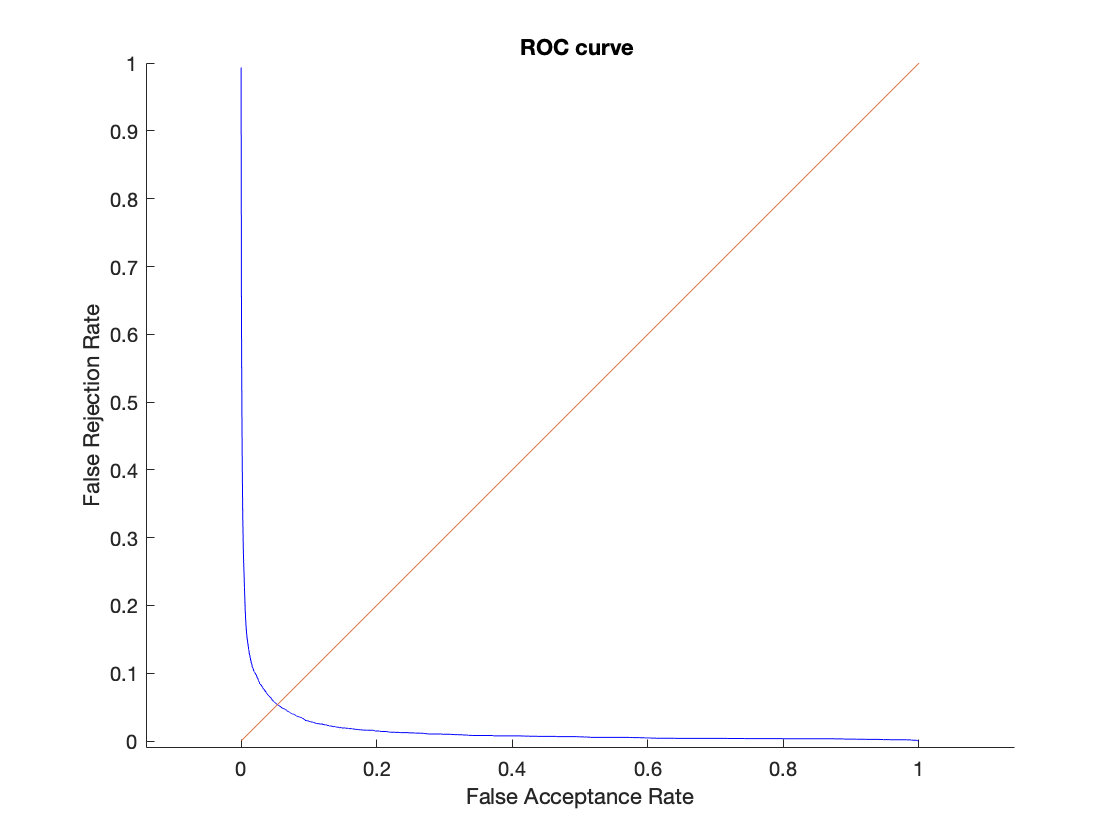

    [val,ind] = sort(deci,'descend');
    roc_y = labelVecBinTest(ind);
	  stack_x_1tmp = cumsum(roc_y == -1);
    stack_x_2tmp = sum(roc_y == -1);
    stack_y_1tmp = (sum(roc_y == 1)-cumsum(roc_y == 1));
    stack_y_2tmp = sum(roc_y == 1);
    stack_x_1{1,i} = stack_x_1tmp;
    stack_x_2{1,i} = stack_x_2tmp;
    stack_y_1{1,i} = stack_y_1tmp;
    stack_y_2{1,i} = stack_y_2tmp;
end
%     

% %%   Consider EACH SESSIONG as a testing sample: Grouping
% %   
%     % Normalize decision value to 0..1;
%     max_deci = max(deci);
%     min_deci = min(deci);
%     deci = (deci-min_deci)/(max_deci-min_deci); 
%     % Start Grouping
%     uniSessionTest = unique(sessionVecTest);
%     newPredictedLabel = zeros(length(uniSessionTest),1);
%     newTrueLabel = zeros(length(uniSessionTest),1);
%     newDeci = zeros(length(uniSessionTest),1);
%     for ii=1:length(uniSessionTest)
%         curIdxTest = find(sessionVecTest==uniSessionTest(ii));
%         newTrueLabel(ii) = unique(labelVecBinTest(curIdxTest)); 
%         curPredictedLabel = l(curIdxTest);
%         curDecisionVal = deci(curIdxTest);
%         count_1 = sum(curPredictedLabel==1);
%         count_minus1 = sum(curPredictedLabel==-1);
%         sumDeci_1 = sum(curDecisionVal(curPredictedLabel==1));
%         sumDeci_minus1 = sum(curDecisionVal(curPredictedLabel==-1));
%         if(count_1 > count_minus1)
%             newPredictedLabel(ii) = 1;
%             newDeci(ii) = sumDeci_1/count_1;
%         elseif (count_1 < count_minus1)
%             newPredictedLabel(ii) = -1;
%             newDeci(ii) = sumDeci_minus1/count_minus1;
%         else
%             if(sumDeci_1>sumDeci_minus1)
%                 newPredictedLabel(ii) = 1;
%                 newDeci(ii) = sumDeci_1/count_1;
%             else
%                 newPredictedLabel(ii) = -1;
%                 newDeci(ii) = csumDeci_minus1/count_minus1;
%             end
%         end
%     end
%     [val,ind] = sort(newDeci,'descend');
%     roc_y = newTrueLabel(ind);
% 	  stack_x_1tmp = cumsum(roc_y == -1);
%     stack_x_2tmp = sum(roc_y == -1); 
%     stack_y_1tmp = (sum(roc_y == 1)-cumsum(roc_y == 1));
%     stack_y_2tmp = sum(roc_y == 1);
%     stack_x_1{1,i} = stack_x_1tmp;
%     stack_x_2{1,i} = stack_x_2tmp;
%     stack_y_1{1,i} = stack_y_1tmp;
%     stack_y_2{1,i} = stack_y_2tmp;
%   end
% %    


% PLOT ROC 
s = cell2mat(stack_x_1);
s2 = sum(s,2);
s3 = cell2mat(stack_x_2);
s4 = sum(s3);
stack_x = s2./s4;
s = cell2mat(stack_y_1);
s2 = sum(s,2);
s3 = cell2mat(stack_y_2);
s4 = sum(s3);
stack_y = s2./s4;
figure(1);
hold on
axis xy
axis([-0.01 1 -0.01 1])
axis equal
plot(stack_x,stack_y,'color','b');
plot([0 1], [0 1]);
xlabel('False Acceptance Rate');
ylabel('False Rejection Rate');
title(['ROC curve ']);
hold off